Simulación 1/7 (Re=1): Error Max=3.270e-02,ErrorMediocuad=6.711e-04 Iter=3.0
Simulación 2/7 (Re=10): Error Max=1.011e-01,ErrorMediocuad=4.729e-03 Iter=3.0
Simulación 3/7 (Re=50): Error Max=1.757e-01,ErrorMediocuad=1.246e-02 Iter=3.0
Simulación 4/7 (Re=100): Error Max=2.162e-01,ErrorMediocuad=1.609e-02 Iter=3.0
Simulación 5/7 (Re=200): Error Max=2.535e-01,ErrorMediocuad=1.914e-02 Iter=3.0
Simulación 6/7 (Re=500): Error Max=2.937e-01,ErrorMediocuad=2.202e-02 Iter=3.0
Simulación 7/7 (Re=1000): Error Max=3.172e-01,ErrorMediocuad=2.339e-02 Iter=3.0


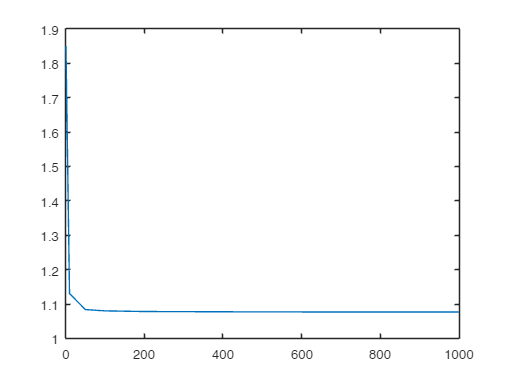

% --- Parámetros Generales ---
a = -10; b = 10;
T_final = 1.0;
Tol = 1e-15; 
MaxIter = 500; 

% --- Configuración  fija ---
Nx_fijo = 160; 
Nt_fijo = 160;

% Valores de Reynolds a estudiar
Re_values = [1, 10, 50, 100, 200, 500, 1000]; 
n_sims = length(Re_values);

% Columna 1: Re, Col 2: ErrorMax, Col 3: ErrorMedio, Col 4: Iteraciones
Resultados = zeros(n_sims, 4);

% Matriz para guardar los perfiles(Cada columna será un Re)
Soluciones_Finales = []; 

vcond=[];
for i = 1:n_sims
    Re_act = Re_values(i);
    
    %Para modificar el metodo modificar el achivo crancknicholson_trabajo
    [x_nodes, t_nodes, U_num, viter, ~,mcond] = CrankNicolson_trabajo(@(t) -1, @(t) 1, 'funcionci', a, b, Nx_fijo, T_final, Nt_fijo, (1/Re_act), Tol, MaxIter);
    
    [T_mesh, X_mesh] = meshgrid(t_nodes, x_nodes);
    U_exact = ExactaBurgers(X_mesh, T_mesh, Re_act, a, b, 'funcionci');
    Error = abs(U_num - U_exact);
    GE = max(Error(:));            
    NE = sqrt(mean(Error(:).^2));  
    iter_promedio = mean(viter);
    Soluciones_Finales(:, i) = U_num(:, end);
    Resultados(i, :) = [Re_act, GE, NE, iter_promedio];
    
    fprintf('Simulación %d/%d (Re=%d): Error Max=%.3e,ErrorMediocuad=%.3e Iter=%.1f\n',i, n_sims, Re_act, GE,NE, iter_promedio);
end

disp(' ');

disp('=== TABLA DE RESULTADOS ===');

=== TABLA DE RESULTADOS ===


disp('   Re        ErrMax      ErrMedio    Iter');

   Re        ErrMax      ErrMedio    Iter


disp(Resultados);

   1.0e+03 *

    0.0010    0.0000    0.0000    0.0030
    0.0100    0.0001    0.0000    0.0030
    0.0500    0.0002    0.0000    0.0030
    0.1000    0.0002    0.0000    0.0030
    0.2000    0.0003    0.0000    0.0030
    0.5000    0.0003    0.0000    0.0030
    1.0000    0.0003    0.0000    0.0030



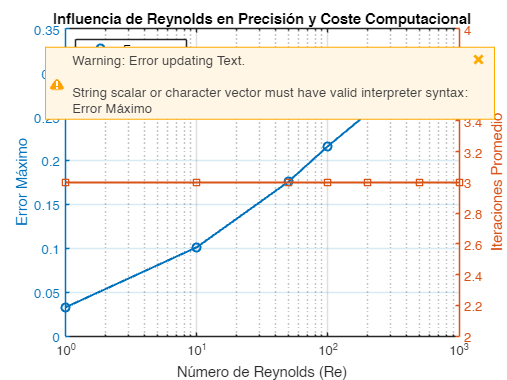



% --- GRAFICAS ---

% Figura 1: Error e Iteraciones (Doble Eje)
% Usamos 'yyaxis' porque las escalas son muy diferentes
figure('Color','w', 'Name', 'Robustez Reynolds');

yyaxis left
% Escala logarítmica en X
semilogx(Resultados(:,1), Resultados(:,2), '-o', 'LineWidth', 1.5, 'MarkerSize', 6);
xlabel('Número de Reynolds (Re)');
ylabel('Error Máximo', 'Interpreter', 'latex');
grid on;

yyaxis right
semilogx(Resultados(:,1), Resultados(:,4), '-s', 'LineWidth', 1.5, 'MarkerSize', 6);
ylabel('Iteraciones Promedio');

title('Influencia de Reynolds en Precisión y Coste Computacional');
legend('Error', 'Iteraciones', 'Location', 'northwest');

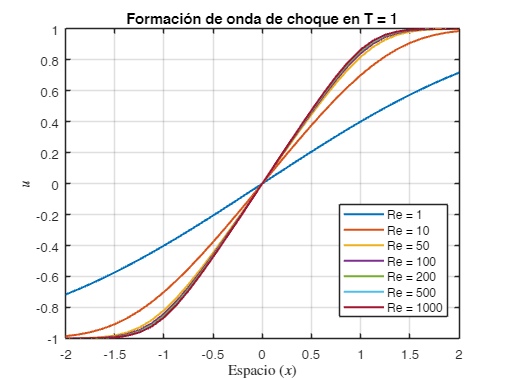


% Figura 2: Perfiles
figure('Color','w', 'Name', 'Perfiles de Choque');
hold on;
box on; % Recuadro alrededor
colores = lines(n_sims); 

for i = 1:n_sims
    
    plot(x_nodes, Soluciones_Finales(:, i), '-', ...
        'LineWidth', 1.5, ...
        'Color', colores(i,:), ...
        'DisplayName', sprintf('Re = %d', Re_values(i)));
end

xlim([-2 2]); % Zoom en la zona interesante
xlabel('Espacio ($x$)', 'Interpreter', 'latex');
ylabel('$u$', 'Interpreter', 'latex');
title(['Formación de onda de choque en T = ' num2str(T_final)]);
legend('Location', 'best');
grid on;